L = [0 1 3 3 2 4 2 3 3 3 0.01; 
    0.1 0 0 0 0 0 0 0 0 0 0; 
    0 0.3 0 0 0 0 0 0 0 0 0; 
    0 0 1.5 0 0 0 0 0 0 0 0; 
    0 0 0 1.2 0 0 0 0 0 0 0; 
    0 0 0 0 2 0 0 0 0 0 0; 
    0 0 0 0 0 1.4 0 0 0 0 0; 
    0 0 0 0 0 0 1.1 0 0 0 0; 
    0 0 0 0 0 0 0 1.01 0 0 0; 
    0 0 0 0 0 0 0 0 0.9 0 0; 
    0 0 0 0 0 0 0 0 0 0.5 0];

n1 = 25; % juveniles 0-3
n2 = 10; % adults 4-6
n3 = 3; % adults 7-9
n4 = 5; % adults 10-12
n5 = 6; % adults 13-15
n6 = 10; % adults 16-18
n7 = 8; % adults 19-21
n8 = 26; % adults 22-24
n9 = 20; % adults 25-27
n10 = 14; % adults 28-30
n11 = 3; % adults 31-33

% lambda population eigen values
[z, lambda] = eig(L) % lambda are eigen vectors which describe the pop. structurelambda = 0.8118;

z =    0.9869 + 0.0000i   0.9278 + 0.0000i   0.9278 + 0.0000i   0.7907 + 0.0000i   0.7907 + 0.0000i   0.7660 + 0.0000i   0.7660 + 0.0000i  -0.8639 + 0.0000i   0.5221 + 0.0000i   0.5221 + 0.0000i   0.0000 + 0.0000i
   0.0860 + 0.0000i   0.0686 - 0.0643i   0.0686 + 0.0643i   0.0195 - 0.0856i   0.0195 + 0.0856i  -0.0352 - 0.0784i  -0.0352 + 0.0784i   0.0923 + 0.0000i  -0.0514 - 0.0378i  -0.0514 + 0.0378i   0.0000 + 0.0000i
   0.0225 + 0.0000i   0.0019 - 0.0285i   0.0019 + 0.0285i  -0.0263 - 0.0126i  -0.0263 + 0.0126i  -0.0192 + 0.0216i  -0.0192 - 0.0216i  -0.0296 + 0.0000i   0.0070 + 0.0223i   0.0070 - 0.0223i  -0.0000 + 0.0000i
   0.0294 + 0.0000i  -0.0276 - 0.0336i  -0.0276 + 0.0336i  -0.0302 + 0.0381i  -0.0302 - 0.0381i   0.0464 + 0.0146i   0.0464 - 0.0146i   0.0474 + 0.0000i   0.0139 - 0.0405i   0.0139 + 0.0405i  -0.0000 + 0.0000i
   0.0308 + 0.0000i  -0.0524 - 0.0069i  -0.0524 + 0.0069i   0.0405 + 0.0505i   0.0405 - 0.0505i  -0.0076 - 0.0650i  -0.0076 + 0.0650i  -0.0607 + 0.0000i  -0

lambda =    1.1473 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.7203 + 0.6745i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7203 - 0.6745i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1999 + 0.8787i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1999 - 0.8787i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000

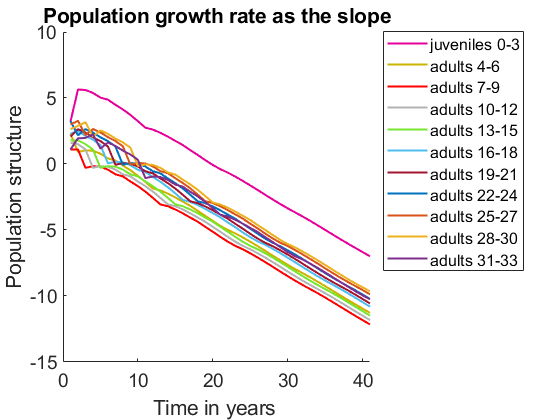


% calculate the growth rate from dominant eigen value
r = log(lambda);

n = [n1; n2; n3; n4; n5; n6; n7; n8; n9; n10; n11];

y = zeros(11,40);

y(:,1) = n;

for t = 1:40
    y(:,t+1) = L * y(:,t);
    n = n + 10;
    L = [0 1 3 3 2 4 2 3 3 3 0.01; 
        0.01 0 0 0 0 0 0 0 0 0 0; 
        0 0.3 0 0 0 0 0 0 0 0 0; 
        0 0 1 0 0 0 0 0 0 0 0; 
        0 0 0 1 0 0 0 0 0 0 0; 
        0 0 0 0 1.4 0 0 0 0 0 0; 
        0 0 0 0 0 0.9 0 0 0 0 0; 
        0 0 0 0 0 0 1 0 0 0 0; 
        0 0 0 0 0 0 0 1.01 0 0 0; 
        0 0 0 0 0 0 0 0 0.9 0 0; 
        0 0 0 0 0 0 0 0 0 0.4 0];
end

T = [1:41];

figure
hold on
plot(T, log(y(1,:)), 'LineWidth',1.5, 'Color',[0.9 0 0.6])
plot(T, log(y(2,:)), 'LineWidth',1.5, 'Color',[0.8 0.7 0])
plot(T, log(y(3,:)), 'LineWidth',1.5, 'Color',[1 0 0])
plot(T, log(y(4,:)), 'LineWidth',1.5, 'Color',[0.7 0.7 0.7])
plot(T, log(y(5,:)), 'LineWidth',1.5, 'Color',[0.4660 0.9 0.1880])
plot(T, log(y(6,:)), 'LineWidth',1.5)
plot(T, log(y(7,:)), 'LineWidth',1.5)
plot(T, log(y(8,:)), 'LineWidth',1.5)
plot(T, log(y(9,:)), 'LineWidth',1.5)
plot(T, log(y(10,:)), 'LineWidth',1.5)
plot(T, log(y(11,:)), 'LineWidth',1.5)
legend('juveniles 0-3', 'adults 4-6', 'adults 7-9', 'adults 10-12', 'adults 13-15', 'adults 16-18', 'adults 19-21', 'adults 22-24', 'adults 25-27', 'adults 28-30', 'adults 31-33', 'Location', 'northeastoutside','FontSize', 12)
title('Population growth rate as the slope','FontSize', 16)
xlabel('Time in years ', 'FontSize', 16)
ylabel('Population structure', 'FontSize', 16)
set(gca,'FontSize',14)
hold off

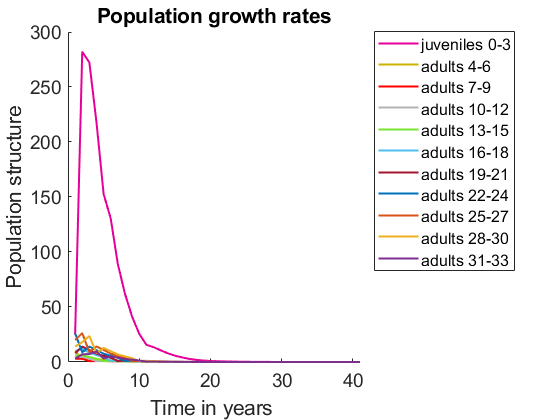


figure
hold on
plot(T, y(1,:), 'LineWidth',1.5, 'Color',[0.9 0 0.6])
plot(T, y(2,:), 'LineWidth',1.5, 'Color',[0.8 0.7 0])
plot(T, y(3,:), 'LineWidth',1.5, 'Color',[1 0 0])
plot(T, y(4,:), 'LineWidth',1.5, 'Color',[0.7 0.7 0.7])
plot(T, y(5,:), 'LineWidth',1.5, 'Color',[0.4660 0.9 0.1880])
plot(T, y(6,:), 'LineWidth',1.5)
plot(T, y(7,:), 'LineWidth',1.5)
plot(T, y(8,:), 'LineWidth',1.5)
plot(T, y(9,:), 'LineWidth',1.5)
plot(T, y(10,:), 'LineWidth',1.5)
plot(T, y(11,:), 'LineWidth',1.5)
legend('juveniles 0-3', 'adults 4-6', 'adults 7-9', 'adults 10-12', 'adults 13-15', 'adults 16-18', 'adults 19-21', 'adults 22-24', 'adults 25-27', 'adults 28-30', 'adults 31-33', 'Location', 'northeastoutside','FontSize', 12)
title('Population growth rates','FontSize', 16)
xlabel('Time in years ', 'FontSize', 16)
ylabel('Population structure', 'FontSize', 16)
set(gca,'FontSize',14)
hold off